# Analysis of Robust Stability (RS) and Robust Performance (RP)

load statespace_data A B C D FWT

% 2 inputs, 2 outputs
s = tf('s');
G = FWT(1:2, 1:2);

% performance weights
wp = [(s/3+0.3*2*pi)/(s+pi*6e-5) 0;
    0 0.05];

wu = [0.005 0;
       0 (0.005*s^2 + 0.0007*s+0.00005)/(s^2 + 0.0014*s + 10^(-6))];

% uncertainty weights
wi1 = ((1/16*pi)*s + 0.3)/((1/64*pi)*s + 1);
wi2 = wi1;

wo1 = (0.05*s + 0.25)/(0.01*s + 1);
wo2 = wo1;

wi = [wi1 0;
      0 wi2];
wo = [wo1 0;
     0 wo2];

## 3. Frequency response of weights

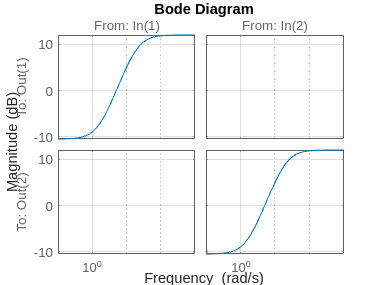

% frequency response of uncertainty weights
figure
bodemag(wi)
grid on

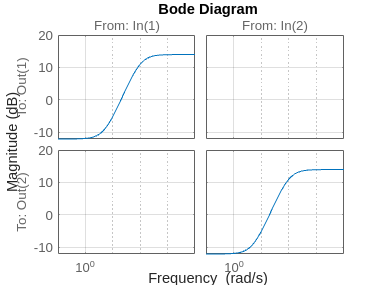


figure
bodemag(wo)
grid on

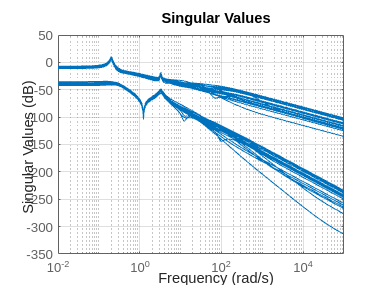


% uncertain TF singular values 

pb1 = ultidyn("idelta", 2);
pb2 = ultidyn("odelta", 2);

wid = wi*pb1;
wod = wo*pb2;

X = (eye(2)+wid)*G*(eye(2)+wod);

figure
sigma(X)
grid on

## 4. Augmented Generalised Plant

% Define plant and in- and outputs
G.u = 'udu';
G.y = 'y';

wp.u = 'v';
wp.y = 'z1';

wu.u = 'u';
wu.y = 'z2';

wo.u = 'y';
wo.y = 'do';

wi.u = 'u';
wi.y = 'di';

% Build system
sumblock1 = sumblk("ydy = y + dy", 2);
sumblock2 = sumblk("udu = u + du", 2);
sumblock3 = sumblk("v = w + ydy", 2);

dP = connect(G, wu, wp, wo, wi, sumblock1, sumblock2, sumblock3, {'du', 'dy', 'w', 'u'}, {'di', 'do', 'z1', 'z2', 'v'});

## 5. Checking NS, NP, RS, RP

load mixedsensitivitycontroller.mat MS_C P CLms

K = MS_C;

% NS - generalised Nyquist
ol = K*G;
tdet = eye(2) - ol;

det = tdet(1,1)*tdet(2,2) - tdet(1,2)*tdet(2,1);

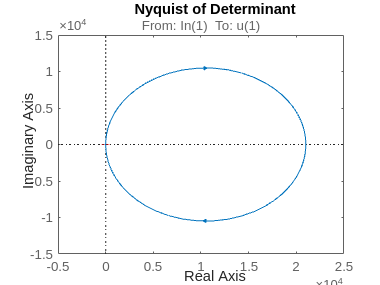


nyquist(det);
title('Nyquist of Determinant')


% NP - ||N||inf < 1
gamma = hinfnorm(CLms);

% RS
N = lft(dP, K);

M = N(1:4, 1:4);

% frequencies to check and shape of Delta block
omega=logspace(-3,4,70);
Mf=frd(M,omega);
blockstructure =  -ones(size(Mf,1),2);

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Mf, blockstructure);

Points completed: 70/70



% norm of bound
muRS = mubnds(:,1);
[muRSinf, muRSw] = norm(muRS,inf);
muRSinf

muRSinf = 0.8094


% 
% Evaluate at frequencies and decide structure on uncertainty
Nf = frd(N,omega);
blockstructureN =  [blockstructure;
    2 4];

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Nf, blockstructureN);

Points completed: 70/70



% norm of bound
muRP = mubnds(:,1);
[muRPinf, muRPw] = norm(muRP,inf);
muRPinf

muRPinf = 1.3317

Delta=[ultidyn('D_1',[1,1]) 0; 0 ultidyn('D_2',[1,1])];
Punc=lft(Delta,dP);
opt=dkitopt('FrequencyVector', omega,'DisplayWhileAutoIter','on')

opt =   dkitopt with properties:

                      Default: [1×1 struct]
              FrequencyVector: [70×1 double]
            InitialController: []
                     AutoIter: 'on'
         DisplayWhileAutoIter: 'on'
      StartingIterationNumber: 1
       NumberOfAutoIterations: 10
                      MixedMU: 'off'
             AutoScalingOrder: [5 2]
       AutoIterSmartTerminate: 'on'
    AutoIterSmartTerminateTol: 0.0050


 
 
 
Iteration Number:  1
--------------------
 

  Test bounds:  9.8 <=  gamma  <=  29

   gamma       X>=0        Y>=0       rho(XY)<1    p/f
  1.7e+01     3.2e-05     0.0e+00     4.994e-03     p

  Best performance (actual): 16
Calculating MU of closed-loop system:
Points completed: 70/70
Iteration Summary            
-----------------------------
Iteration #                 1
Controller Order           12
Total D-Scale Order         0
Gamma Acheived         16.200
Peak mu-Value          11.886
 
Auto Fit in Progress 
	 Block 1, MaxOrder=5, Order = 0
	 Block 2, MaxOrder=5, Order = 0
	 Block 3, MaxOrder=5, Order = 0
 
 
 
Iteration Number:  2
--------------------
 

  Test bounds:  6.9 <=  gamma  <=  14

   gamma       X>=0        Y>=0       rho(XY)<1    p/f
  9.9e+00     3.2e-05     0.0e+00     1.367e-02     p
  8.3e+00     3.2e-05     0.0e+00     5.861e-02     p
  7.6e+00    -1.9e+03 #  -6.5e-18     3.381e-03     f

  Best performance (actual): 8.3
Calculating MU of closed-loop sy

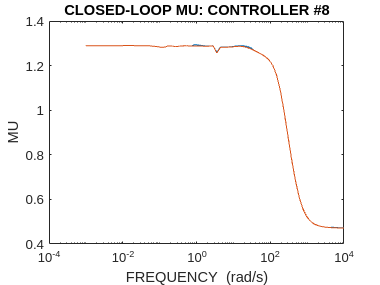

[K,clp,bnd,dkinfo]=musyn(Punc,2,2,opt);